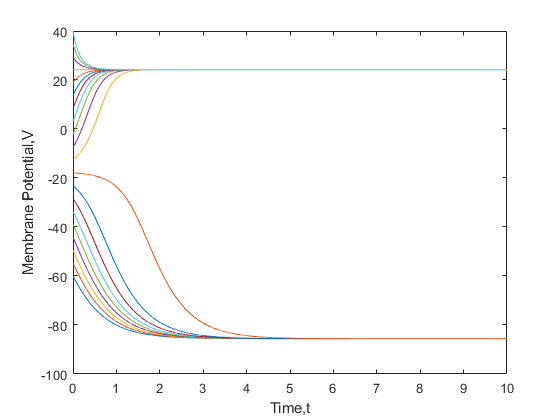

dt = 0.001;
time = 10;
loop  = ceil(time/dt);
t = (1:loop)*dt;

C=10;
I=-400;
gl=19;
El=-67;
gna=74;
Ena=60;

vt=20;
v=zeros(loop,vt);
v(1,:)=linspace(-60,40,vt);

for j=1:vt
    for i=1:loop-1
        v(i+1,j) = v(i,j)+dt*(I - gl*(v(i,j)-El)-gna*infi(v(i,j),1.5,16)*(v(i,j)-Ena))/C;
    end
end

figure
plot(t,v)
xlabel('Time,t');
ylabel('Membrane Potential,V');

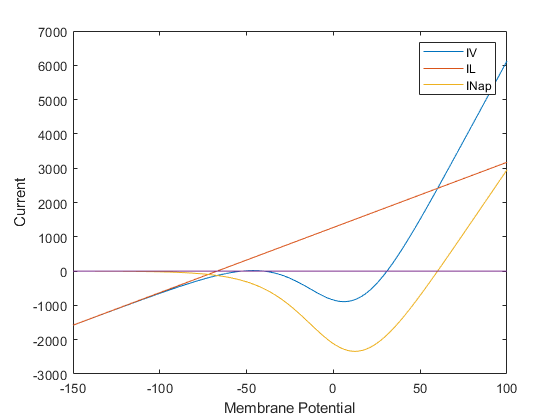

% plotting I-V
V = -150:0.001:100;
IV=zeros(length(V),1);
Il=zeros(length(V),1);
Inap=zeros(length(V),1);

for i=1:length(V)
    IV(i) = gl*(V(i)-El)+gna*infi(V(i),1.5,16)*(V(i)-Ena);
    Il(i)=gl*(V(i)-El);
    Inap(i)=gna*infi(V(i),1.5,16)*(V(i)-Ena);
end

ax=zeros(length(V),1);
figure
plot(V,IV,V,Il,V,Inap,V,ax)
legend('IV','IL','INap')
xlabel('Membrane Potential');
ylabel('Current');

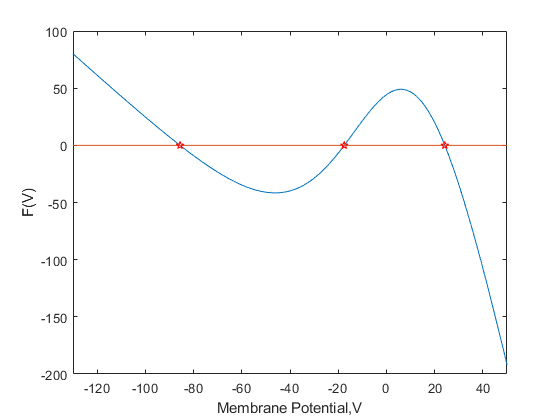

%plotting Fv
Fv=(I-IV)./C;
figure
k1=find(abs(Fv-ax)<0.0225);
V1=V(k1);
y1=zeros(1,length(V1));
plot(V,Fv,V,ax,V1,y1,'rp')
set(gca, 'XLim',[-130 50]);
xlabel('Membrane Potential,V');
ylabel('F(V)');

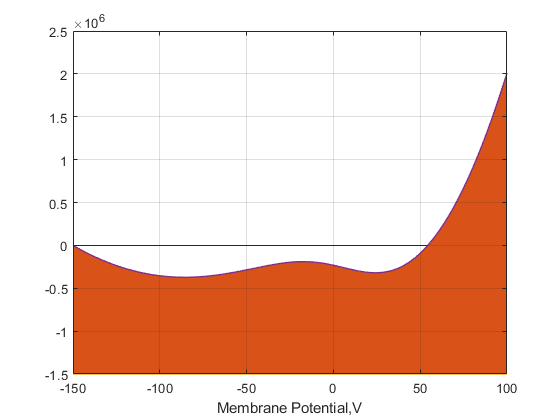

% 大致模拟小球自由运动模型
V_low = ones(length(V),1)*(-1500000);
V_do = -Fv;
V_sim=zeros(length(V),1);
for i=1:length(V)-1
    V_sim(i+1)=V_sim(i)+0.1*V_do(i);
end
figure
shadedplot(V,V_low',V_sim');
xlabel('Membrane Potential,V');

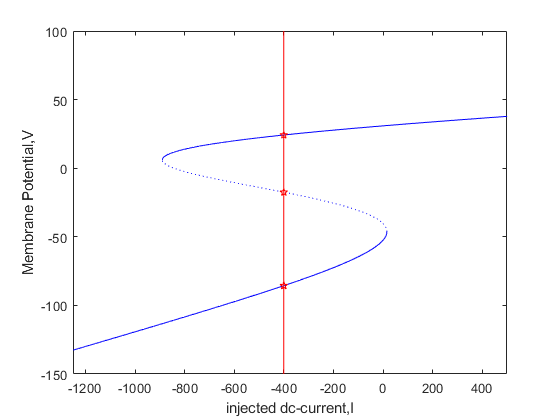

% 相位图
[peakdata,locs1] = findpeaks(IV);
[mindata,locs2] = findpeaks(-IV);
Is=ones(length(V),1)*I;
k2=find(abs(IV-Is)<0.225);
V2=V(k2);
y2=ones(1,length(V2))*I;
figure;
plot(IV(1:locs1,1),V(1,1:locs1),'b-', ...
    IV(locs1:locs2,1),V(1,locs1:locs2),'b:', ...
    IV(locs2:length(V),1), V(1,locs2:length(V)),'b-', ...
    Is,V,'r',y2,V2,'rp')
set(gca, 'XLim',[-1250 500]);
xlabel('injected dc-current,I');
ylabel('Membrane Potential,V');